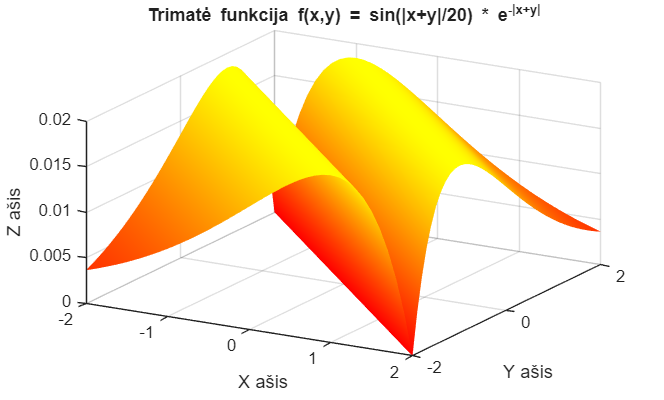

[x, y] = meshgrid(-2:0.1:2, -2:0.1:2);

z_a = sin(abs(x + y) / 20) .* exp(-abs(x + y));

figure(1);
surf(x, y, z_a);
colormap("autumn");       
shading interp;         
view(30, 30);           
grid on;

title('Trimatė funkcija f(x,y) = sin(|x+y|/20) * e^{-|x+y|}');
xlabel('X ašis');
ylabel('Y ašis');
zlabel('Z ašis');

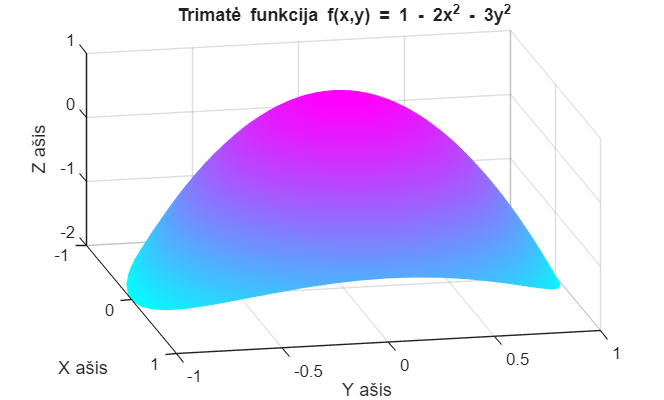

[theta, r] = meshgrid(linspace(0, 2*pi, 50), linspace(0, 1, 50));

x_b = r .* cos(theta);
y_b = r .* sin(theta);

z_b = 1 - 2*x_b.^2 - 3*y_b.^2;

figure(2);
surf(x_b, y_b, z_b);
colormap("cool");       
shading interp;         
view(78, 30);           
grid on;

title('Trimatė funkcija f(x,y) = 1 - 2x^2 - 3y^2');
xlabel('X ašis');
ylabel('Y ašis');
zlabel('Z ašis');

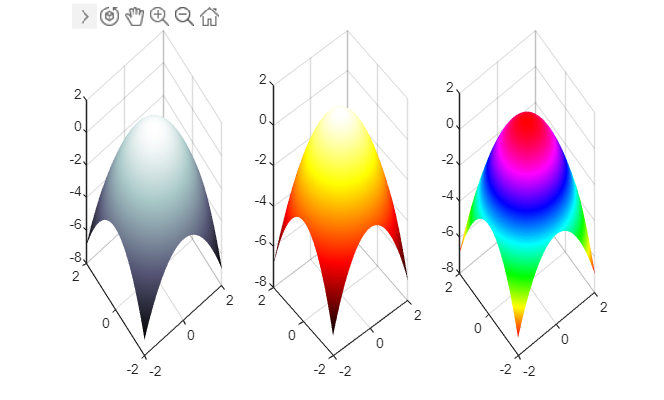

[x, y] = meshgrid(-2:0.1:2, -2:0.1:2);

z = 1 - (x.^2 + y.^2);

ax1 = subplot(1, 3, 1);
surf(x, y, z);
colormap(ax1, "bone"); 
shading interp;          

ax2 = subplot(1, 3, 2);
surf(x, y, z);
colormap(ax2, 'hot');    
shading interp;

ax3 = subplot(1, 3, 3);
surf(x, y, z);
colormap(ax3,"hsv");   
shading interp;